# Load data

load('mk1____2022-06-09_14-54.mat');
load('anomalydata.mat');
numChannels = 1

numChannels = 1

# Visualize data

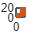

%Plot figure
figure(1);
plot(data.dataGalga, 'LineWidth',3);
hold on;
plot(data.timeStamp, 'LineWidth',3);

# Extract normal data

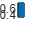

%Selection slow period
pos2=find(data.timeStamp==2);
pos4=find(data.timeStamp==4);
pos=[pos2  pos4];

%Create normal data
normaldata=data.dataGalga(pos);

%Plot figure
figure(2);
plot(normaldata, 'LineWidth',3);

## Detrend data

%Detrend train data
normaldata_detr=detrend(normaldata);
anomalydata_detr=detrend(anomalydata);

## Standarize data

%Standarize train data
XA=normalize(normaldata_detr)';
%Standarize test data
XB=normalize(anomalydata_detr)';

